clear;

%t1 = linspace(0, 2, samples);
%t2 = linspace(2, 4, samples);

%y = piecewise(0 < t < 2,t-1,2 < t < 4, 3-t);
%fplot(y)

T = 4

T = 4

N = 4

N = 4

samples = 200

samples = 200

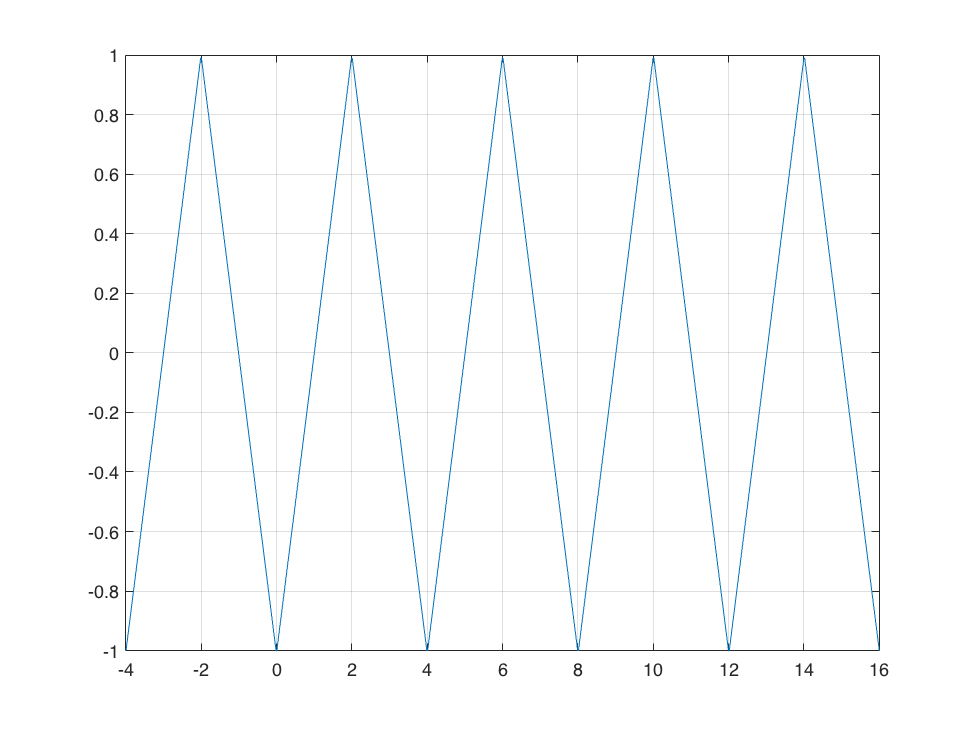


f = @(t)(t-1).*(0<=t & t<=2) + (3-t).*(2<=t & t<=4);

x = linspace(0,T,samples);

intvl = [-T, N*T];
periodic_fx = repmat(f(x),1,N+1);
periodic_x = linspace(intvl(1),intvl(2),length(periodic_fx));
plot(periodic_x, periodic_fx)
grid


fs = 1

fs = 1

sum=0

sum = 0

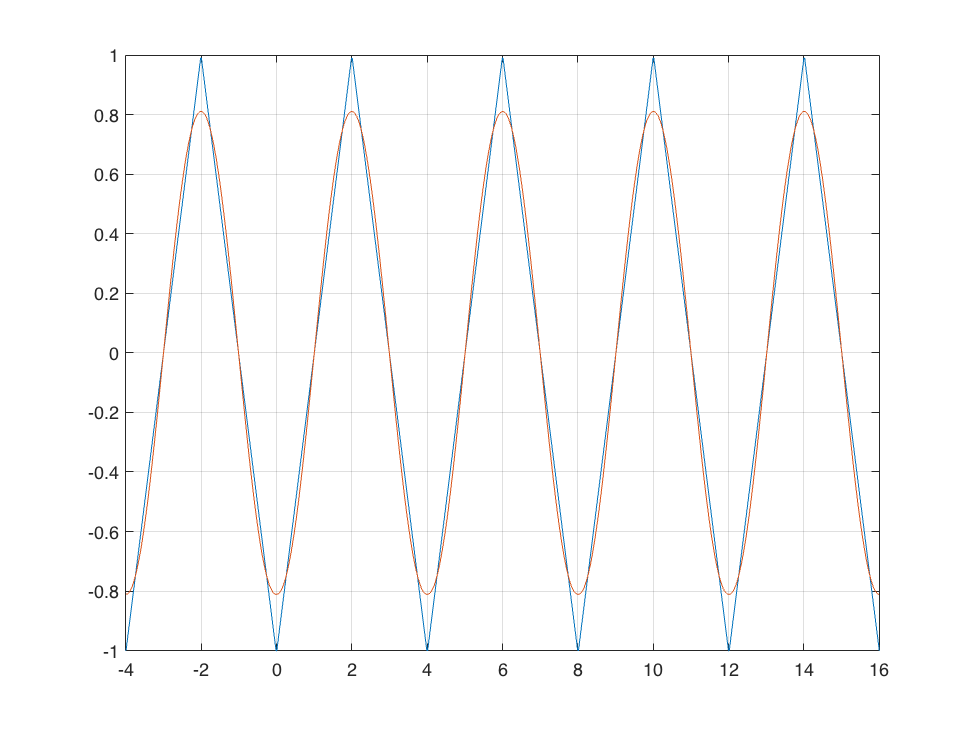

for n=1:2:fs
    an=(4)/(n*pi)^2*(-1+(-1)^n); 
    sum=sum+(an*cos(n*pi*x*1/2));
end 

periodic_sum = repmat(sum,1,N+1);

%plot(x,f(x))
plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
grid

%fplot(x,y,[-8 8]); 
%grid on;hold on;  
%fplot(x,(sum+a0/2),[-8,8]); 




clear;
clc;
%t1 = linspace(0, 2, samples);
%t2 = linspace(2, 4, samples);

%y = piecewise(0 < t < 2,t-1,2 < t < 4, 3-t);
%fplot(y)

A = 1

A = 1

T = 2*pi

T = 6.2832

N = 1

N = 1

samples = 200

samples = 200

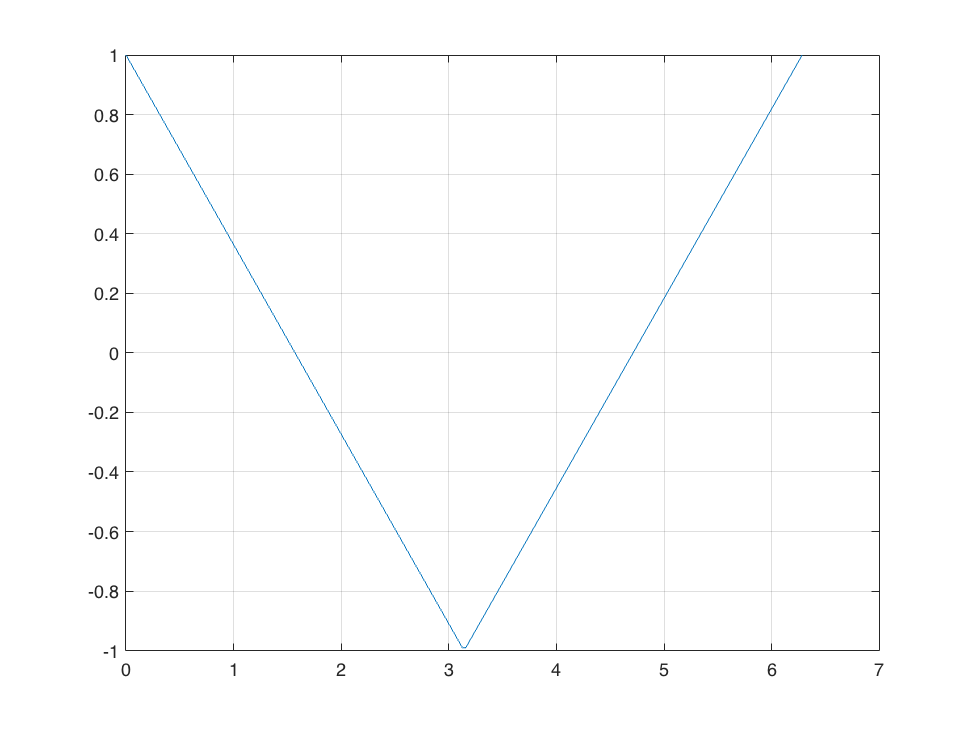


f = @(t) (1-(2*t/pi)).*(0<=t & t<=pi) + ((2*t/pi)-3).*(pi<=t & t<=2*pi);

x = linspace(0,T,samples);

intvl = [-T,T*N];
plot(x,f(x))
grid



periodic_fx = repmat(f(x),1,N+1);
periodic_x = linspace(intvl(1),intvl(2),length(periodic_fx));
plot(periodic_x, periodic_fx)
grid

fs = 3

fs = 3

sum=0

sum = 0

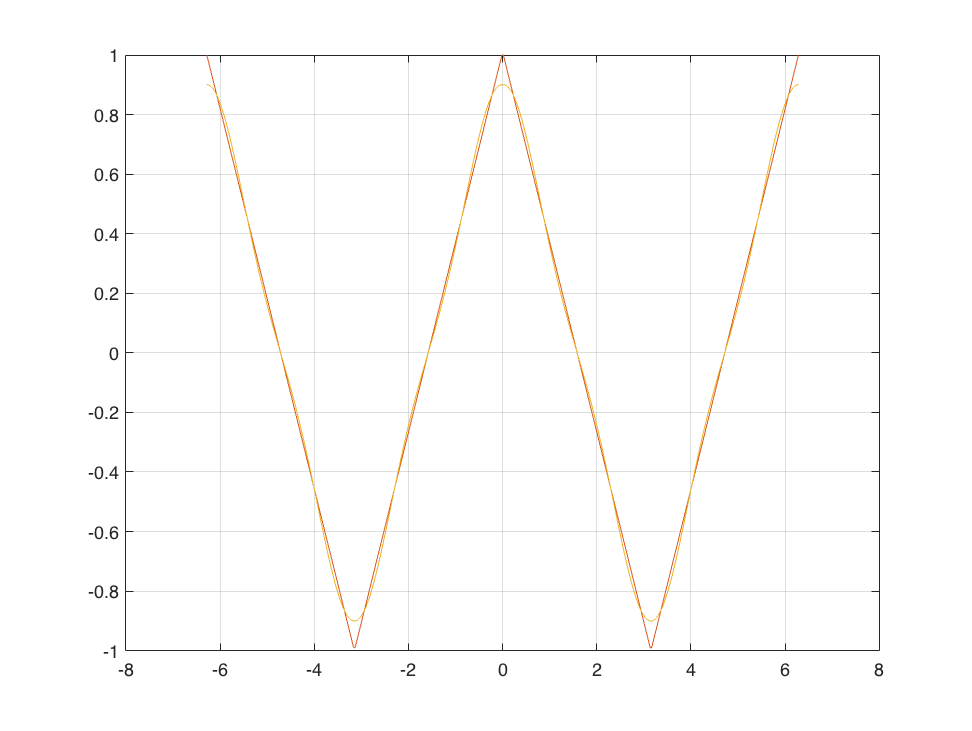

for n=1:2:fs
        %finding the coefficients 
    an=(8)/(n*pi)^2; 
    sum=sum+(an*cos(n*x));
    hold on;
end
   % plot(x,sum)

periodic_sum = repmat(sum,1,N+1);
plot(periodic_x, periodic_fx,periodic_x,periodic_sum)

%fplot(x,y,[-8 8]); 
%grid on;hold on;  
%fplot(x,(sum+a0/2),[-8,8]); 


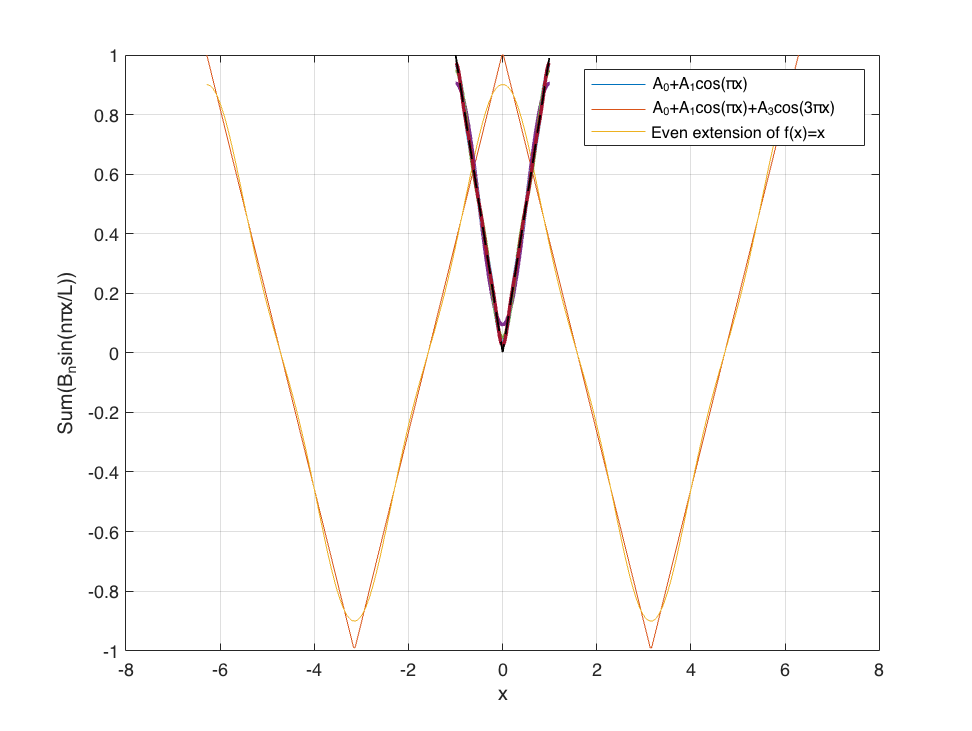

% clear;
% hold off
L     = 1;                        % Length of the interval
x     = linspace(-2*L/2, 2*L/2, 300); % Create 300 points on the interval [-3L, 3L]
Const = -4*L/pi^2;                % Constant in the expression for A_n
Cn    = L / 2;                    % The baseline of the cosine series: A0 = L/2

for n = 1 : 2 : 7                 % Only sum over odd integers
    An = Const/n^2;               % Coefficients inversely proportional to n^2
    Fn = An * cos(n*pi*x/L);      % Calculate Fourier cosine term
    Cn = Cn + Fn;                 % Add the term to Fourier cosine series sum
    plot(x, Cn, 'linewidth', 2);  % Plot the cosine fourier sum
    hold on;
end

xlabel('x'); ylabel('Sum(B_nsin(n\pix/L))');
plot(x, abs(mod(x+1,2)-1),  'k--', 'linewidth', 1); % Trickiest part of the code: create triagular wave
legend('A_0+A_1cos(\pix)', 'A_0+A_1cos(\pix)+A_3cos(3\pix)', 'Even extension of f(x)=x');
hold off;